# DSP HW2 Program Assignment

### 1. Let x[n] = h[n] = ${\left(0\ldotp 9\right)}^n \;$u[n] and y[n] = x[n]*h[n]  

### (a) Determine y[n] analytically and plot the first 99 non-zero samples using the stem function

        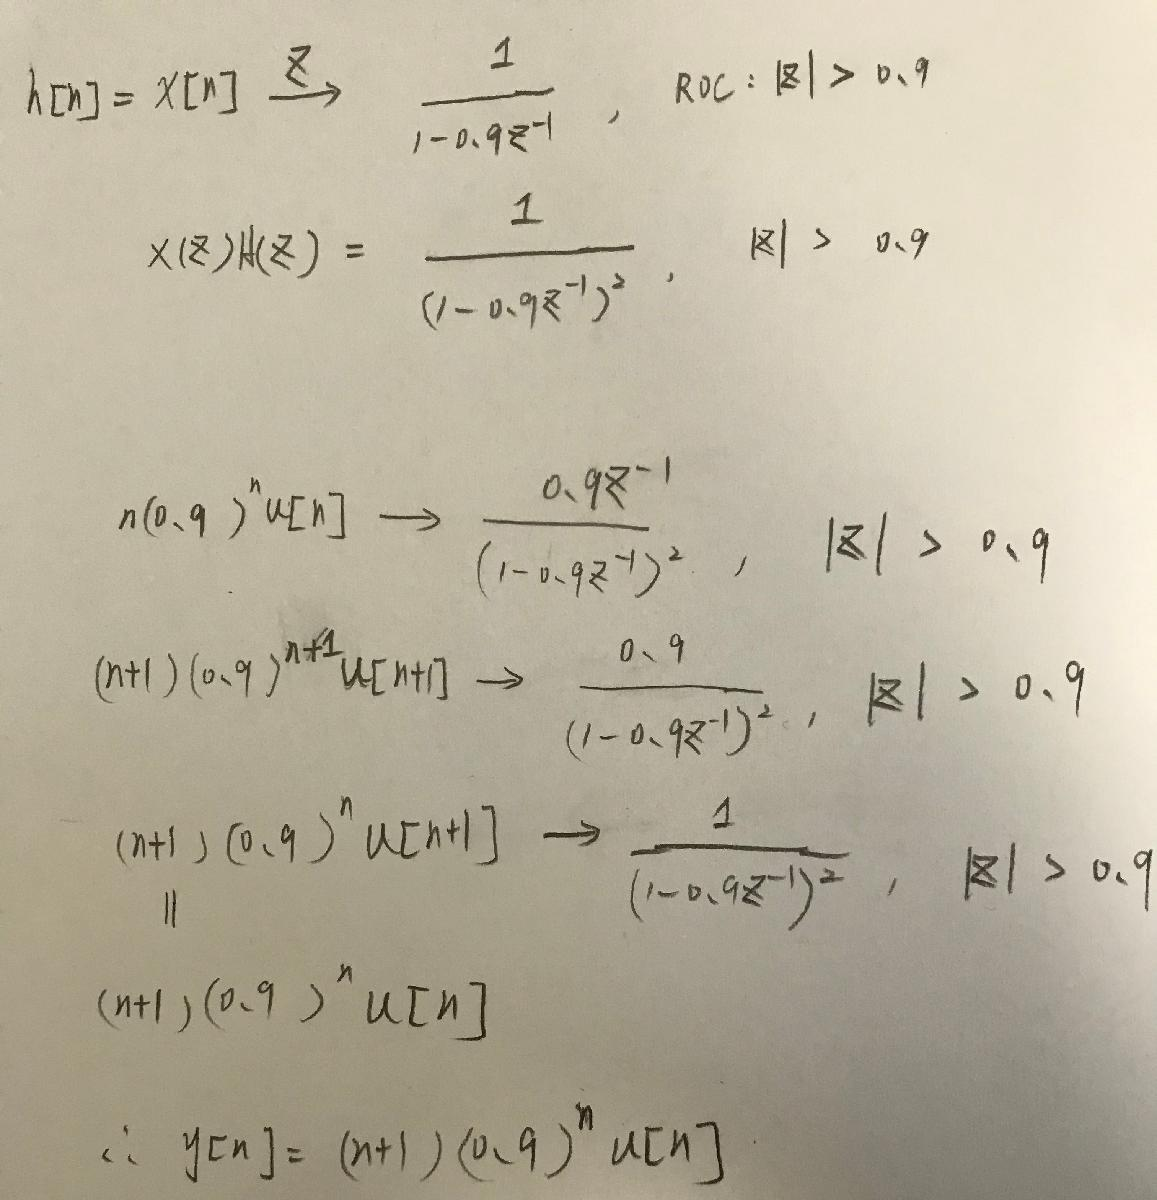

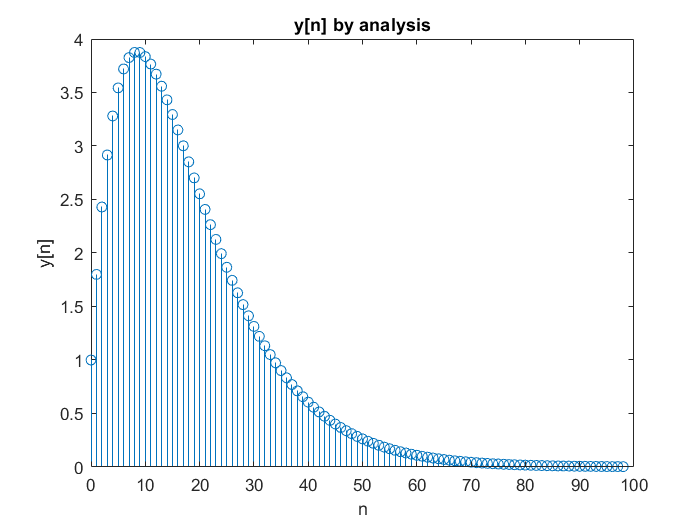

N = 99;
y = zeros(1, 99);  %pre-allocate y
for n = 1:N
    y(n) = n*0.9^(n-1);
end
index = 0:98;
stem(index, y);
xlabel("n");
ylabel("y[n]")
title("y[n] by analysis");

### (b) Take first 50 samples of x[n] and ℎ[n]. Compute and plot y[n] using the conv function.

    I draw the analytical result from (a) and signal from thie problem together to compare their difference. 

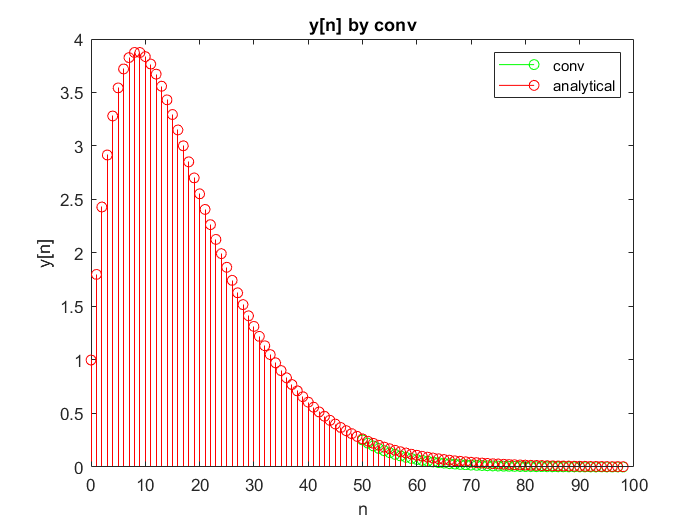

N = 50;
f = zeros(1, 50);  %pre-allocate f
for n = 1:N
    f(n) = 0.9^(n-1);
end
x = f(1:50);
h = f(1:50);
y_b = conv(x, h);
plot_b = stem(index, y_b, 'g');
xlabel("n");
ylabel("y[n]")
title("y[n] by conv");
hold on
plot_a = stem(index, y, 'r');
hold off
legend([plot_b plot_a],{'conv','analytical'})

### (c) Using the filter function, determine and plot the first 99 samples of y[n].

        I draw the analytical result from (a) and signal from thie problem together to compare their difference. 

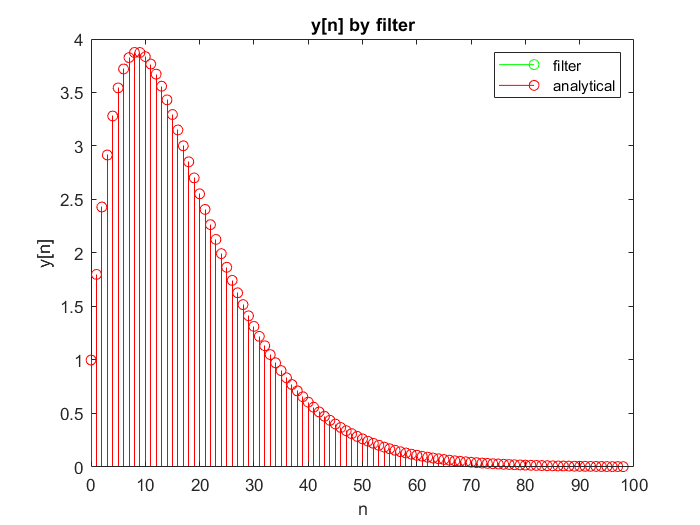

N = 99;
f = zeros(1, 99);  %pre-allocate f
for n = 1:N
    f(n) = 0.9^(n-1);
end
h = f;
x = f;
y_c = filter(h, 1, x); %system = h/1
plot_c = stem(index, y_c, 'g');
xlabel("n");
ylabel("y[n]")
title("y[n] by filter");
hold on
plot_a = stem(index, y, 'r');
hold off
legend([plot_c plot_a],{'filter','analytical'})

### (d) Which of the outputs in (b) and (c) come close to that in (a)? Explain

As graph shown in (b) and (c), there is basically no difference between analytical result and filter function result. And there are some slight differences between analytical and conv function result at n > 50. So the output in (c) comes close to that in (a). I think the reason is filter can apply a system using impulse response coefficient to the input, which will output the the same result as what I analyze in (a). But conv function in (b) only takes the first 50 points although points at n > 50 is small, it slightly the output result as shown in (b)

### 2. The sum $A_x =\sum_n x\left\lbrack n\right\rbrack$ can be thought of as a measure of the "area"  under a sequence x[n].                                                                                                                                                              

### (a) Starting with the convolution sum (2.36), show that $A_y$= $A_x A_h$ (derive in the live script) 


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =\sum_k x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \Longrightarrow A_y =\sum_m y\left\lbrack m\right\rbrack =\sum_m \sum_k x\left\lbrack k\right\rbrack h\left\lbrack m-k\right\rbrack =\;\\
\sum_k \sum_m h\left\lbrack m-k\right\rbrack x\left\lbrack k\right\rbrack =\sum_k x\left\lbrack k\right\rbrack \sum_m h\left\lbrack m-k\right\rbrack =A_h \sum_k x\left\lbrack k\right\rbrack =A_h A_x 
\end{array}$$


### (b) Given the sequences 

###     x =sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); h=ones(1,5);

### compute y[n] = h[n] * x[n], check whether $A_y$= $A_x A_h$ and use the subplot function plot x[n] and y[n] on the same graph. 

x =sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h = ones(1, 5);
y = conv(h, x);
Ay = sum(y);
Ax = sum(x);
Ah = sum(h);
disp(['Ah*Ax = ',num2str(Ah*Ax)])

Ah*Ax = 3.2872


Ay

Ay = 3.2872

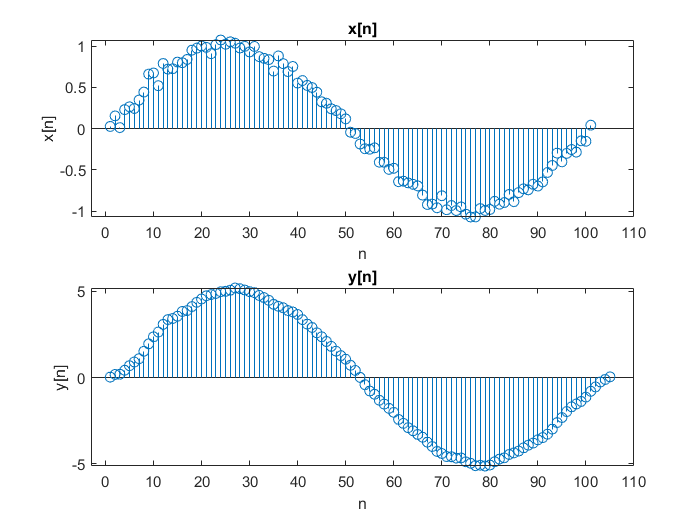

%areEssentiallyEqual = abs(Ay-Ah*Ax) < 200*eps(Ay)


subplot(2,1,1);
stem(x);
xlim([-3 110])
title('x[n]');
xlabel('n');
ylabel('x[n]');
subplot(2,1,2);
stem(y);
xlim([-3 110])
title('y[n]');
xlabel('n');
ylabel('y[n]');

According ot ouptut result, $A_y =A_x A_h$

### (c)Normalize h[n] so that $A_h$ = 1 and repeat part(b).

h = 0.2*ones(1, 5);
y = conv(h, x);
Ay = sum(y);
Ax = sum(x);
Ah = sum(h);
disp(['Ah*Ax = ',num2str(Ah*Ax)])

Ah*Ax = 0.65745


Ay

Ay = 0.6574

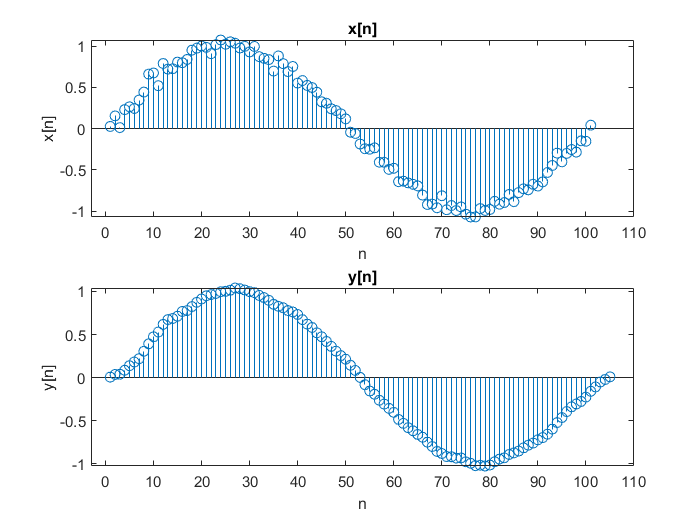

%areEssentiallyEqual = abs(Ay-Ah*Ax) < 200*eps(Ay)


subplot(2,1,1);
stem(x);
xlim([-3 110])
title('x[n]');
xlabel('n');
ylabel('x[n]');
subplot(2,1,2);
stem(y);
xlim([-3 110])
title('y[n]');
xlabel('n');
ylabel('y[n]');

### (d) If $A_h =1,$ then $A_y$ = $A_x$. Use this result to explain the difference between the plots obtained in parts (b) and (c).

Ans: Amplitude of y[n] in part (b) is about 5 and that of y[n] in part (c) is about 1. By the dedinition of convolution, firstable, h[n] becomes h[-n], then h[-n] starts shift **right.** Then when it moves to the peak of x[n], whose value is about 1, y[n] is about 1*1+1*1+1*1+1*1+1*1=5 (when h[n] is normalized in part (b)) and about 0.2*1+0.2*1+0.2*1+0.2*1+0.2*1 = 1 (when h[n] is normalized in part (c)). 

    Also since h[n] is five consecutive same values, it wil make x[n] more smooth especially all five same data point multiplied by x[n]. Because x[n] is a sine funciton with random numbers added at each data point and doing convolution would add  5 consecutive x[n] points together, which could cancel out the random number influence and make the curve smooth. 

### 3. The response of a LTI system to the input x[n] = u[n] is y[n] = 2$\cdot {\left(\frac{1}{3}\right)}^n \cdot u\left\lbrack n\right\rbrack \ldotp$

### (a) Find the impulse response h[n] of the system, and check the results using the function **filter**.

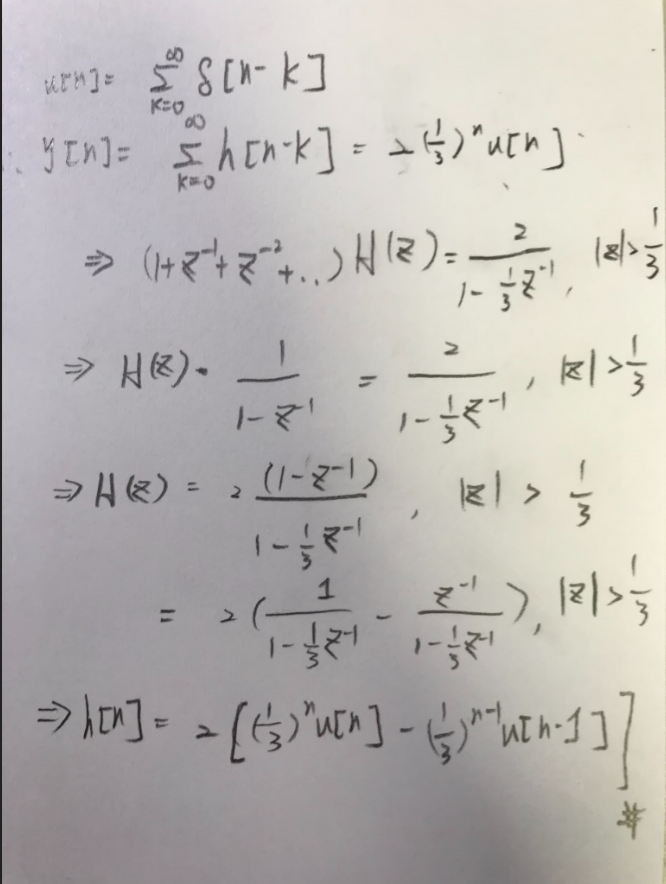

b = [2, -2];
a = [1, -1/3];
t = (-5:1:5)';
x = t >= 0;    
y = filter(b, a, x)

y =          0
         0
         0
         0
         0
    2.0000
    0.6667
    0.2222
    0.0741
    0.0247


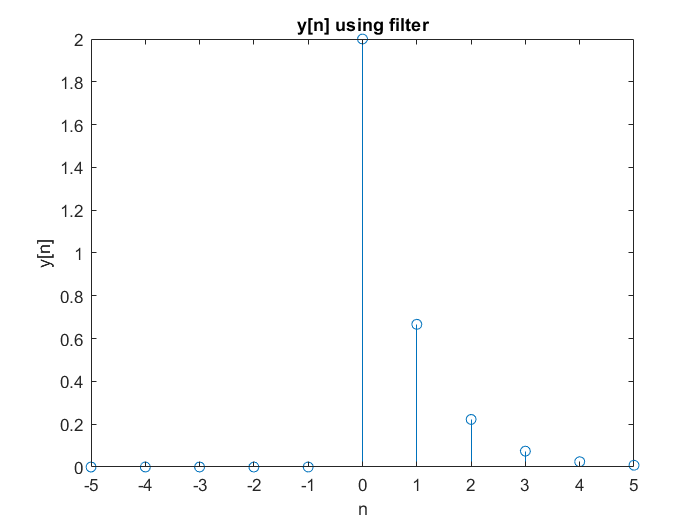

figure;
stem(-5:5, y);
title('y[n] using filter');
xlabel('n');
ylabel('y[n]');

As shown in the output sequence y and its plot, y[n] is equal to $2\times {\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$

### (b)Plot the pole-zero pattern using the function zplane(b, a)

subplot(1, 1, 1);

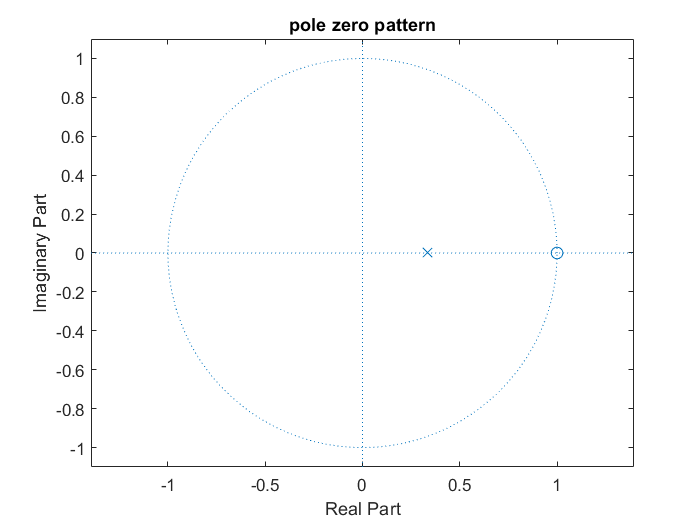

zplane(b, a)
title('pole zero pattern');

### (c)Compute and plot the impulse response using the functions filter and stem. Compare with the plot obtained using the function impz

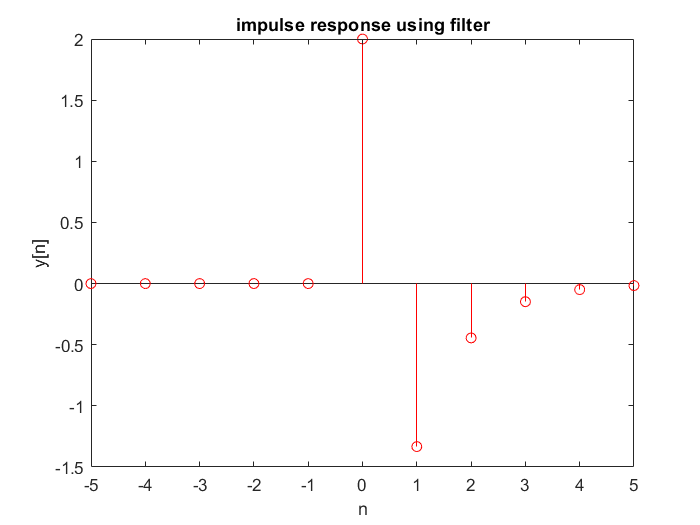

t = (-5:1:5)';
x = t == 0;   %delta function
y = filter(b, a, x);
stem(-5:1:5, y, 'r')
title("impulse response using filter");
xlabel('n');
ylabel('y[n]');

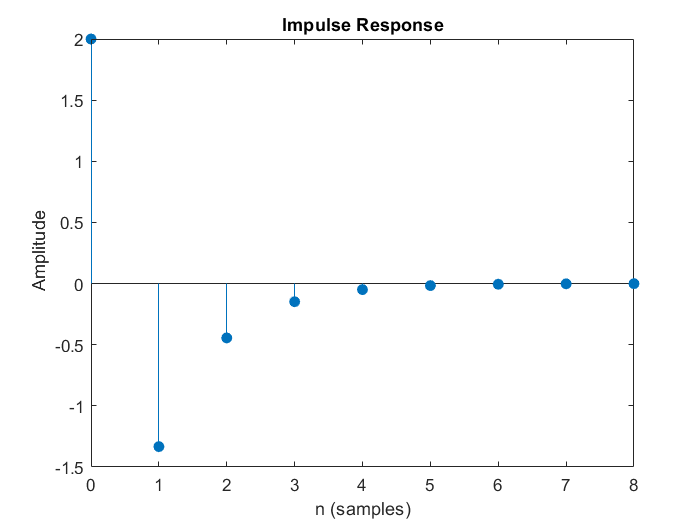

impz(b, a);

Plot from filter and impz are the same as shown at the ouptut graph.

### (d)Use the function residuez and the z-transform pairs in Table 3.1 to find an analytical expression for the impulse response h[n].

[A, p, C] = residuez(b,a)

A = -4

p = 0.3333

C = 6


$$X\left(z\right)=\sum_0^{M-N} C_k z^{-k} +\sum_0^N \frac{A_k }{1-P_k z^{-1} }$$



$$H\left(z\right)=6+\frac{-4}{1-\frac{1}{3}z^{-1} },|z|>\frac{1}{3}\;\left(\mathrm{according}\;\mathrm{to}\;3\ldotp \left(a\right),\;\mathrm{ROC}\;\mathrm{of}\;H\left(z\right)\;\mathrm{is}\;|z|>\frac{1}{3}\right)$$



$$\Longrightarrow h\left\lbrack n\right\rbrack =6\delta \left\lbrack n\right\rbrack -4{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$$


### 4. Find the impulse response of the system (3.97) for the case of real and equal poles and use the result to determine how the location of the poles affects

### (a) the stability of the system

   H(z) = $\frac{\left(b_0 +b_1 z^{-1} \right)}{1+a_1 z^{-1} +a_2 z^{-2} }=$$\frac{z\left(b_0 z+b_1 \right)}{z^2 +a_1 z+a_2 }$. (poles = $\frac{\left(-a_1 \pm \sqrt{a_1^2 -4a_2 }\right)}{2}$) To have equal and real poles, $a_1^2 =4a_2$, then pole is z = $-\frac{a_1 }{2}\ldotp$ If the system stable, ROC has to include unit circle (i.e. |z| = 1). If pole is on unit circle |$a_1 |$ = 2. 

### (b) the shape of the impulse response. (Hint: Use MATLAB to replicate Figure 3.10 for a double pole, find C and discuss stability of the three cases |$a_1$|<C, |$a_1$|= C, |$a_1$| > C) 

If pole is on unit circle,  |$a_1 |$ = 2. Hence, we set **C = 2** to discuss the shape of impulse response when |$a_1 |<2,|a_1 |=2\;\mathrm{and}\;|a_1 |>2$ respectively. Also since position of  zero will not affect the stability of the system, I can assume $b_0 =b_1 =1$

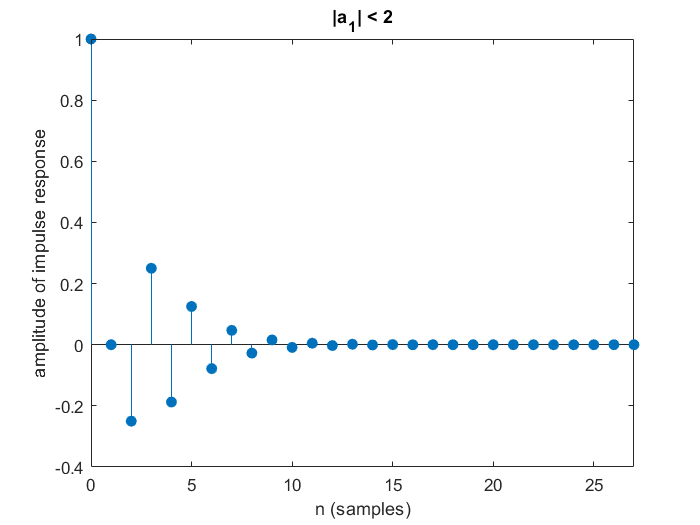

b = [1 1];
a1_case1 = [1 1 1/4];  % |a1| < 2
a1_case2 = [1 2 1];  % |a1| = 2
a1_case3 = [1 3 9/4]; % |a1| > 2
impz(b, a1_case1);
title('|a_{1}| < 2');
ylabel('amplitude of impulse response');

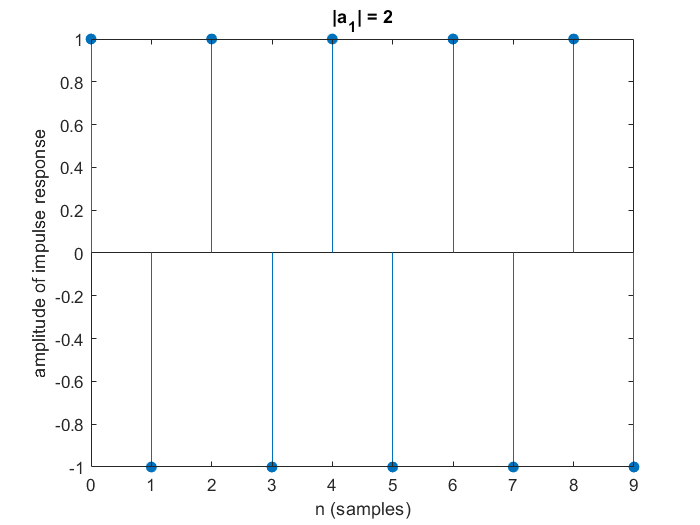

impz(b, a1_case2);
title('|a_{1}| = 2');
ylabel('amplitude of impulse response');

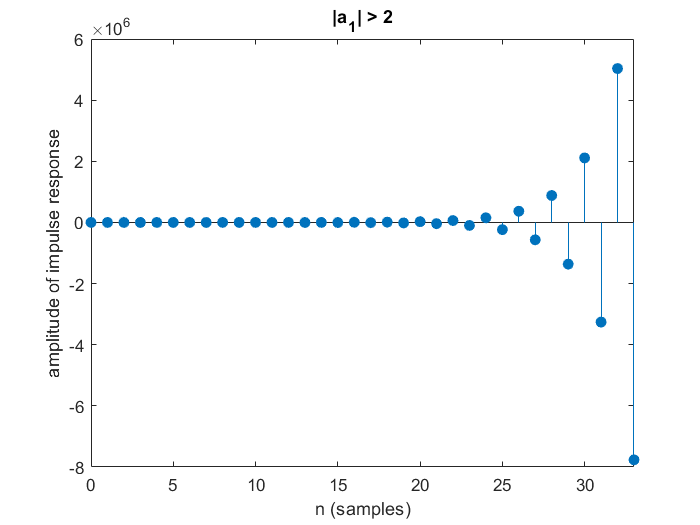

impz(b, a1_case3);
title('|a_{1}| > 2');
ylabel('amplitude of impulse response');

So accordign three different figures under different value of $a_1$, we can find only whne $a_1$ < 2, the system has the stable impulse response. (i.e. both poles has to be located inside the unit circle, the system would be stable.)

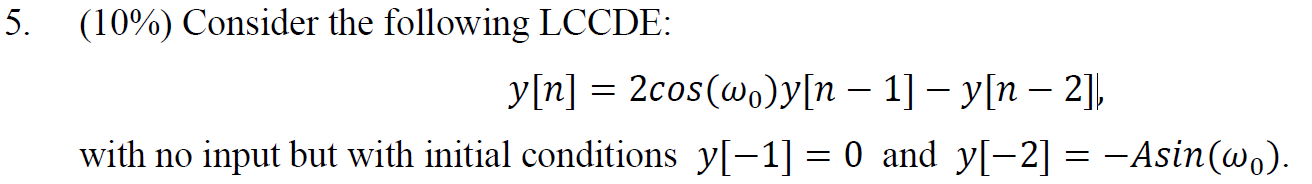

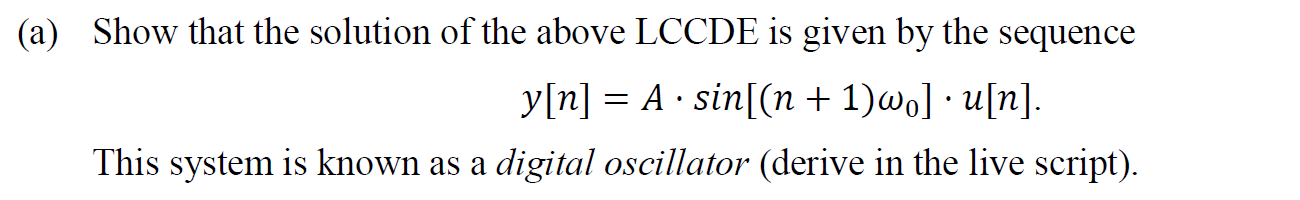

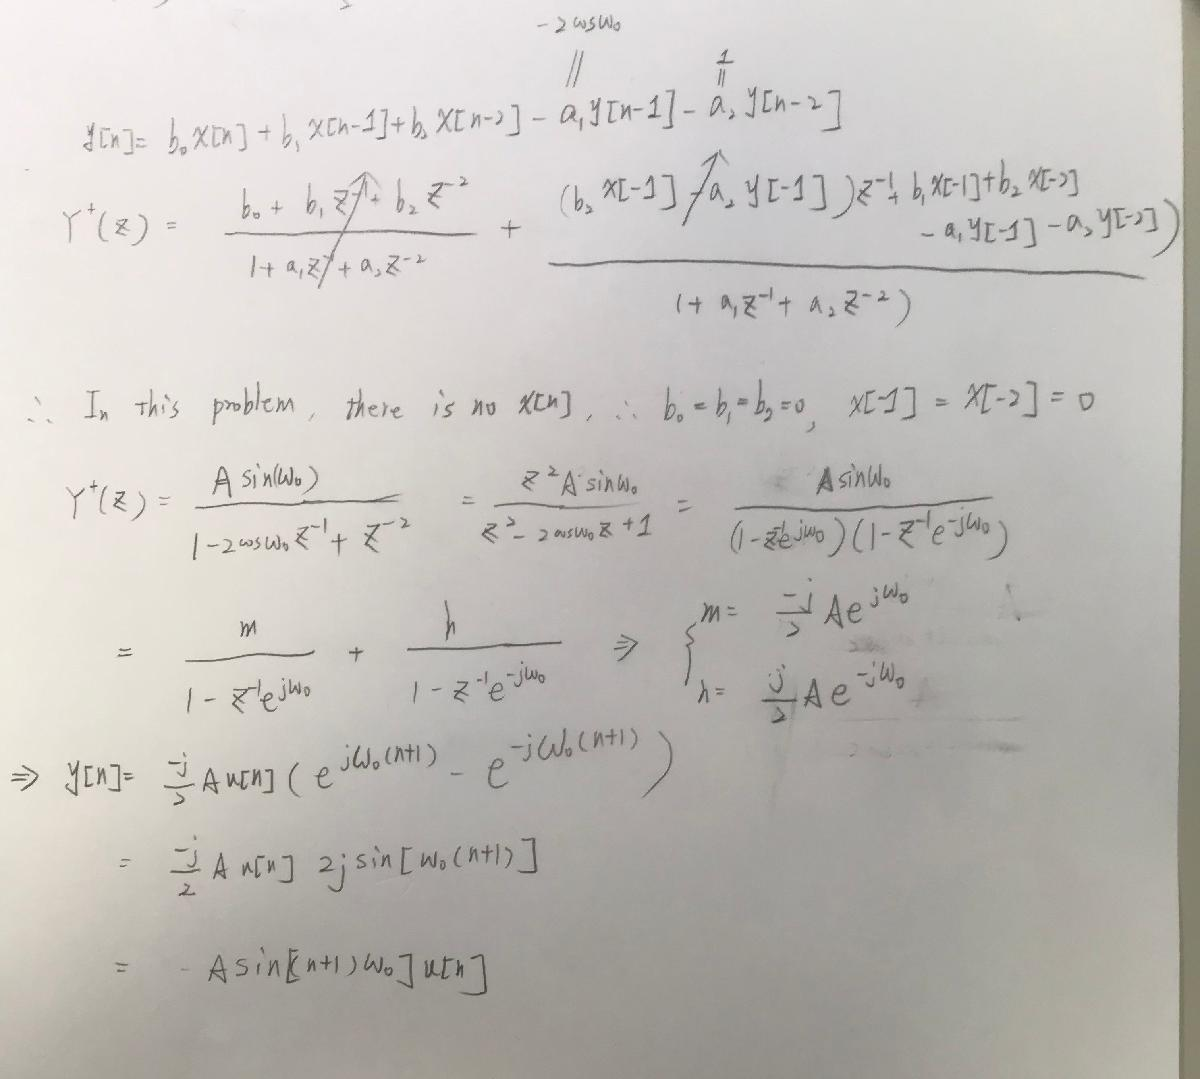

#### (b) For A = 2 and $\omega$ = 0.1$\pi$, verify the operation of the above digital oscillator using the filtc and the filter function. (Hint: check one-sized z-transform in supplement)

According to (a), y[n] = 2$\times$$\begin{array}{l}
\sin \left\lbrack \left(n+1\right)\times 0\ldotp 1\times \pi \right\rbrack u\left\lbrack n\right\rbrack \Longrightarrow \textrm{period}=20\;i\ldotp e\ldotp N=20\ldotp \\
\textrm{Therefore}\;I\;\textrm{input}\;\;\textrm{zeros}\;\textrm{function}\;\textrm{with}\;\textrm{length}=20\;\;\;\left(\textrm{zeros}\left(1,20\right)\right)\;\textrm{to}\;\\
\textrm{see}\;20\;\textrm{complete}\;\textrm{period}\;\textrm{of}\;y\left\lbrack n\right\rbrack \;\textrm{as}\;\textrm{filter}\;\\
\textrm{function}\;\textrm{will}\;\textrm{produce}\;\textrm{the}\;\textrm{output}\;\textrm{with}\;\textrm{the}\;\textrm{length}\;\textrm{of}\;\textrm{input}\;\textrm{signal}\ldotp 
\end{array}$

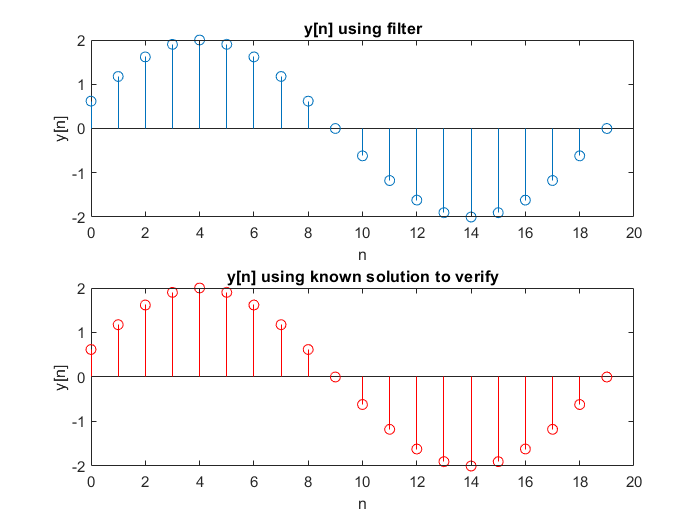

A = 2;
w = 0.1*pi;
b = [0 0 0];
a1 = -2*cos(0.1*pi);
a2 = 1;
a = [1 a1 a2];
yic =  [0 -A*sin(0.1*pi)];
xic = [0 0];
zic = filtic(b, a, yic, xic);
y = filter(b, a, zeros(1, 20), zic);
subplot(2, 1, 1);
stem(0:19, y);
title('y[n] using filter');
xlabel('n');
ylabel('y[n]');
subplot(2, 1, 2);
n = 0:19;
y_ans = 2*sin(w*(n+1));
stem(n, y_ans, 'r');
title('y[n] using known solution to verify');
xlabel('n');
ylabel('y[n]');

According to the output grpah, signal using filter and signal using known solution are the same. Hence, the operation of part (a) is correct. 

### 6. In this problem we illustrate the numerical evaluation of DTFS using MATLAB

### (a) Write a function c=dtfs0(x) which computes the DTFS coefficients (4.67) of a periodic signal and verify the result with dtfs function.

x = [5, 13, 1, -9, 32];
dtfs0(x)

ans =    8.4000 + 0.0000i   5.0756 + 2.4384i  -6.7756 + 4.1357i  -6.7756 - 4.1357i   5.0756 - 2.4384i


dtfs(x)

ans =    8.4000 + 0.0000i   5.0756 + 2.4384i  -6.7756 + 4.1357i  -6.7756 - 4.1357i   5.0756 - 2.4384i


round(dtfs0(x), 5) == round(dtfs(x), 5)

ans = 1×5 logical array
   1   1   1   1   1


% subplot(2, 1, 1);
% stem(dtfs0(x));
% title('dtfs0');
% xlabel('k');
% ylabel('C_{k}')
% subplot(2, 1, 2);
% stem(dtfs(x));
% title('dtfs');
% xlabel('k');
% ylabel('C_{k}')

觀察兩者四捨五入至小數點後第5位的結果，dtfs & dtfs0 皆產生相同的結果 (Values of logical array are all equal to 1)。

### (b) Write a function x=idtfs0(c) which computes the inverse DTFS (4.63) and verify the result with idtfs function

x = [5, 13, 1, -9, 32];
c = [1, 2, 3, 4, 5];
round(idtfs0(c), 5) == round(idtfs(c), 5)

觀察兩者四捨五入至小數點後第5位的結果，idtfs & idtfs0 皆產生相同的結果 (Values of logical array are all equal to 1)。

### 7. Determine and plot the magnitude and phase spectra of the following periodic sequences:

### (a) $x_1$[n]=4⋅cos(1.2$\pi$n+$\frac{\pi }{3}$)+6⋅sin(0.4$\pi$n−$\frac{\pi }{6}$)

    Ans: period of cos(1.2$\pi$n+$\frac{\pi }{3}$) and sin(0.4$\pi$n−$\frac{\pi }{6}$) are both equal to 5. So period of $x_1 \left\lbrack n\right\rbrack$ is 5, i.e. N = 5.

    N$C_k =\sum_0^{N-1} x\left\lbrack n\right\rbrack e^{-\mathrm{j2}\frac{\pi }{N}\mathrm{kn}}$ I got Fourier series coefficient $C_k$ by calling **dfts** function. And x-axis is k, y-axis is |N$C_k |$. ${\mathrm{Also},\;\omega }_k \;\;\left(=2\frac{\pi }{N}k\right)\mathrm{is}\;\mathrm{the}\;\mathrm{corresponed}\;\mathrm{angular}\;\mathrm{frequency}\;\mathrm{at}\;\mathrm{index}=k,\mathrm{so}\;x-\mathrm{axis}\;\mathrm{can}\;\mathrm{also}\;\mathrm{be}\;\mathrm{represented}\;\mathrm{by}\;\omega_k \;\mathrm{as}\;\mathrm{well}\ldotp \;$I use the same notation through 7 (a), (b), (c).

n = 0:4;
x1 = 4*cos(1.2*pi*n+pi/3)+6*sin(0.4*pi*n-pi/6);
c = dtfs(x1);
N = 5;
mag = N*abs(c); 
figure;
stem(n, mag);
title('magnitude');
xlabel('k');
ylabel('|NC_{k}|');
phase = angle(c);
stem(n, phase);
title('phase');
xlabel('k');
ylabel('phase (radian)');

### (b) $x_2$[n]={1,1,0,1,1,1,0,1}, (one period)

        period = N = 8

N = 8;
x2 = [1, 1, 0, 1, 1, 1, 0, 1];
c =dtfs(x2);
mag = N*abs(c);
figure;
stem(mag, 'r');
title('magnitude');
xlabel('k');
ylabel('|NC_{k}|');
phase = angle(c);
stem(phase, 'r');
title('phase');
xlabel('k');
ylabel('\angle phase (radian)');

### (c) $x_3$[n]=1−sin($\frac{\pi }{4}$n), 0≤n≤11 (one period)

    period = N = 8.

n = 0:11;
N = 12;
x3 = 1-sin(pi/4*n);
c =dtfs(x3);
mag = N*abs(c);
figure;
stem(n, mag, 'g');
title('magnitude');
xlabel('k');
ylabel('|NC_{k}|');
stem(n, angle(c), 'g');
title('phase');
xlabel('k');
ylabel('\angle phase (radian)');

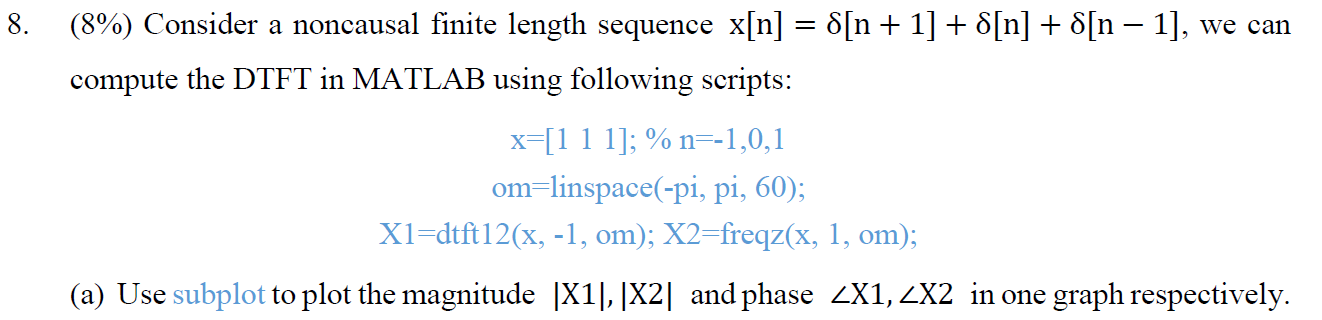

x = [1 1 1]; %n = -1, 0, 1
om = linspace(-pi, pi, 60);
X1 = dtft12(x, -1, om);
X2=freqz(x, 1, om);
subplot(2,1,1);
stem(om/pi, abs(X1));
title('magnitude X_{1}');
xlabel('\omega/\pi');
ylabel('|X_{1}e^{j\omega}|)');
subplot(2,1,2);
stem(om/pi, abs(X2), 'g');
title('magnitude X_{2}');
xlabel('\omega/\pi');
ylabel('|X_{2}e^{j\omega}|');
figure;
subplot(2,1,1);
stem(om/pi, angle(X1)/pi);
title('phase X_{1}');
xlabel('\omega/\pi');
ylabel('\angle X_{1}e^{j\omega}/\pi');
subplot(2,1,2);
stem(om/pi, angle(X2)/pi, 'g');
title('phase X_{2}');
xlabel('\omega/\pi');
ylabel('\angle X_{2}e^{j\omega}/\pi');

### (b) Is the magnitude |X1|=|X2| ? Is the phase ∠X1=∠X2 ? If not, Explain.

Ans: the magnitude is the same, but the phase it different. Fourier transform is  

X$\left(e^{{\mathrm{jw}}_k } \right)=\sum_{N_1 }^{N_2 } x\left\lbrack n\right\rbrack e^{-{\mathrm{jw}}_k n_} ={\;e}^{-{\mathrm{jw}}_k N_1 _} \sum_0^{N_2 -N_1 } x\left\lbrack n+N_1 \right\rbrack e^{-{\mathrm{jw}}_k n_}$**freqz **always assumes $N_1 =0$. Therefore, when $N_1 \not= 0,\;$for each frequency component $\omega_k$, its phase will be affected by  ${\;e}^{-{\textrm{jw}}_k N_1 _}$, but as${|\;e}^{-{\textrm{jw}}_k N_1 _}$| = 1, magnitude is not affected (both of them have the same magnitude response).

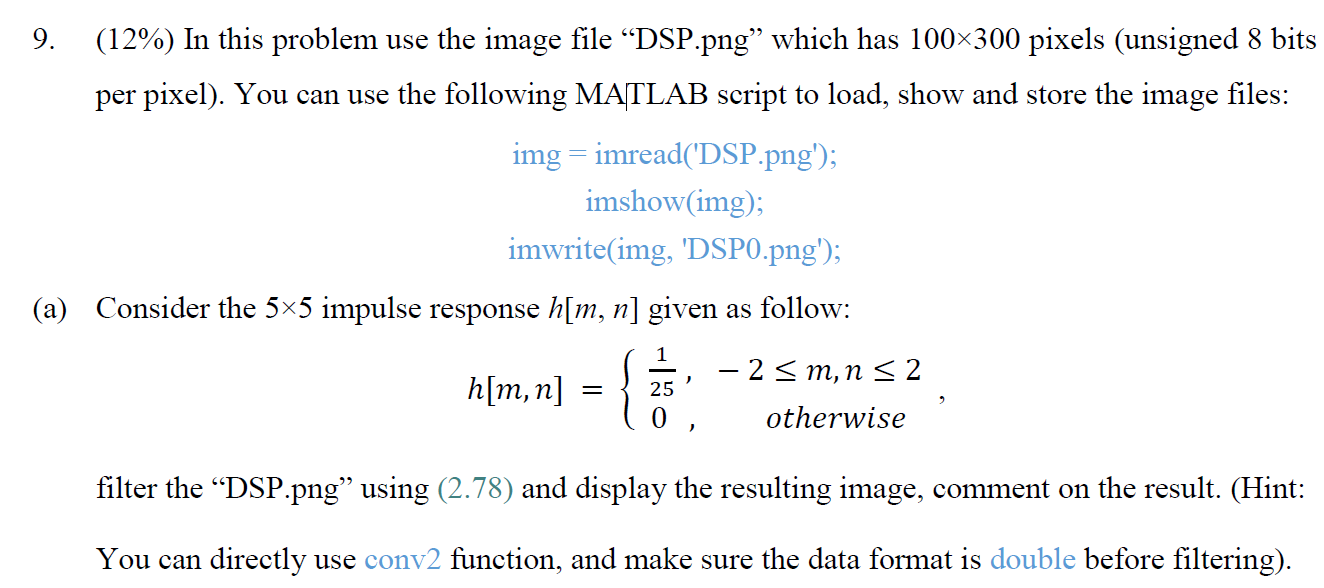

img = imread('DSP.png');
figure;
disp('Original');

Original


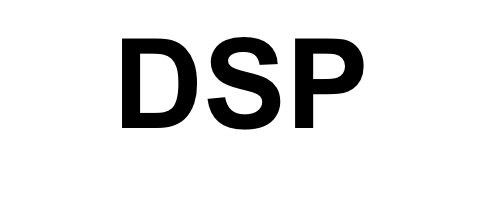

imshow(img);

h = (1/25)*ones(5, 5);
img = double(img);
img = conv2(h, img);
%imwrite(img, 'DSP_a.png');
img = uint8(img);
disp('After filtering');

After filtering


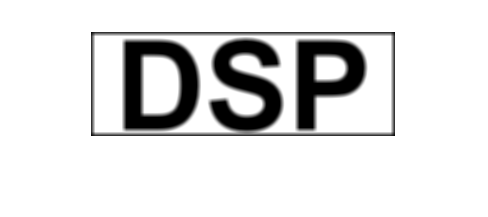

imshow(img);

### Comment: h[m, n] is a average filter, it will average 25 pixels value around each pixel of the original photo and create the filterd photo. After filtering, there appears black border. it's because when doing filtering on the pixels near the borders, h[m, n] covers the black word (DSP), after averaging, there appears black border around the border. Also the word (DSP becomes more soft), it's because h[m, n] covers white part of the photo, after averaging, the word beomes less black and a little blur as well.

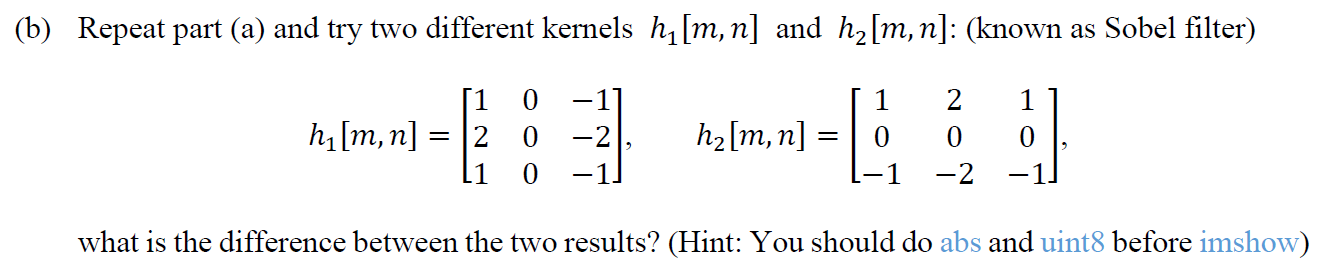

h1 = [1 0 -1; 2 0 -2; 1 0 -1];
h2 = [1 2 1; 0 0 0; -1 -2 -1];
img = imread('DSP.png');
img_double = double(img);
img_h1 = conv2(h1, img_double);
img_h1 = abs(img_h1);
img_h1 = uint8(img_h1);
%imwrite(img_h1, 'DSP_h1.png');
figure;
disp('h1 filter');
imshow(img_h1);
img_h2 = conv2(h2, img_double);
img_h2 = abs(img_h2);
img_h2 = uint8(img_h2);
%imwrite(img_h2, 'DSP_h2.png');
disp('h2 filter');
imshow(img_h2);

### Difference between the two results: Sobel filter is used for edge detection, where the pixel value change sharply. In this problem, there are only two colors in the picture. (black and white) Hence, the edges are located at the pixels between black and white parts of image. Sobel filter has two directions, horizontal and vertical. $h_1$ is the horizontal one. and $h_2$ is the vertical one. Horizontal sobel filter will detect the edge in the horizontal direction. As shown at the the result from $h_1 \;\mathrm{filter}$, edge on the horizontal has been highlighted in white. No sharp change of pixel value in the horizontal direction is black, such as upper and lower part of  word (DSP) and white all black and white part of image except edge. As the result from $h_2$ filter shows, the edge on the vertical part has been hightlight in white. No sharp change of pixel value in vertical direction is black, such as left part of 'D' and 'p'. I noted that as 'S' has sharp pixel value change in both direction except upper and lower part of 'S'. Therefore, the border of 'S' is almost all highlighted at two pictures.    

img_h1 = filter2(h1, img_double);
img_h1 = abs(img_h1);
img_h1 = uint8(img_h1);
%imwrite(img_h1, 'DSP_h1.png');
figure;
imshow(img_h1);
img_h2 = filter2(h2, img_double);
img_h2 = abs(img_h2);
img_h2 = uint8(img_h2);
%imwrite(img_h2, 'DSP_h2.png');
imshow(img_h2);

### Difference between the two functions: `conv2(image, h) is the same as filter2(rot90(h,2), image). rot90(h, 2) means rotate h (kernel) 180° counterclockwise. In this two problem, `$h_1$` is still horizontal edge detection filter and `$h_2$ is still vertical edge detection filter. The only difference is that before taking absolute value, (result from conv2) = -(result from filter2). So after taking absolute value, the iamge matrix value is the same, that's why photos from (b) and (c) are the same.

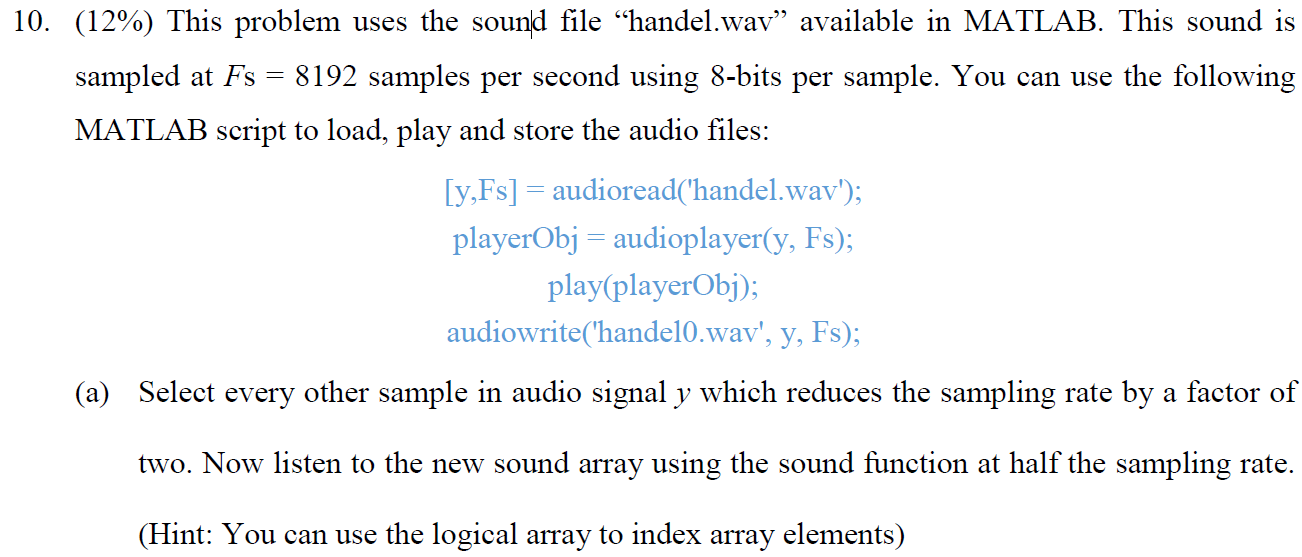

%Fs = 8192;
[y, Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
play(playerObj);

% x = [1 0; 0 1];
% n = floor(length(y)/4); % [1 0] repeat times
% B = repmat(x,n,1);    
% B = logical(B);
% y_a = y(B);
y_a = y(1:2:length(y));
playerObj = audioplayer(y_a, Fs/2);
play(playerObj);
% audiowrite('handel.wav', y, Fs);

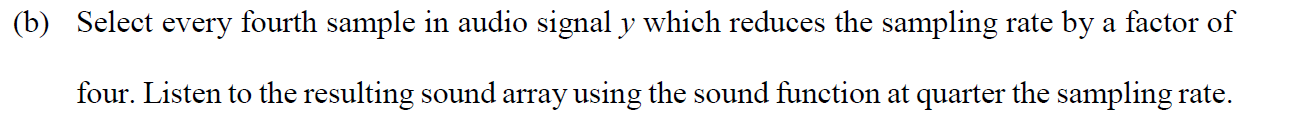

% a = 1;
% for n=1:length(y)
%     if mod(n, 4) == 0 
%         y_b(a) = y(n);
%         a = a + 1;
%     end
% end
y_b = y(1:4:length(y));
playerObj = audioplayer(y_b, Fs/4);
play(playerObj);

### (c) From the results of (a) and (b), what do you discover?

### Ans: They are all low-pitched compared with original sound and the pitch from (b) is lower than (a). That's because their frequency has decreased throung downsampling. And (b)'s sampling rate is down by a factor of four. (a)'s sampling rate is down by a factor of two. Hence, (b) sounds more low-pitched.   